# Plot Hydrogen curves for a ROI in tsne diagram

This script allows you to select a region from the t-sne diagram by drawing a polygon, and plotting all the hydrogen curves from this region of the diagram. To this end, it will draw the tsne-diagram again, and allow you to select a region of it to draw the hydrogen vs voltage curves in it.

It requires that the matlab workspace contains the following variables, as produced by the  StepbyStep script: voltagebins, TsneTab, HydrogenTab, EstTab, ElementsAmountsMarkers

## First, decide if you want to plott the H2/H ratio or the frqction of H2 or H

This script can either draw the ratio of H2 by H2 or simply the ionic fractions of H2 and H. Here you can pick which one you want.

wewanttoplot = "H2byH";
%wewanttoplot = "H2";
%wewanttoplot = "H";

## Open a new Figure and draw the tsne diagram again.

This will be neede to select a region of interest

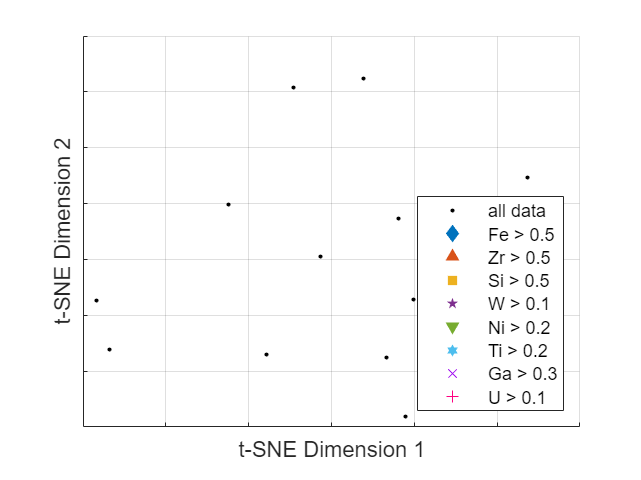

DrawTSNEDiagram(TsneTab, EstTab, ElementsAmountsMarkers);

tsneax = gca;

## Select Region of Interest

Now we use the drawpolygon function to allow the user to draw a polygon onto the tsne diagram. It works as follows: 

- Run the code cell below and hit enter to start drawing

- Draw a polygon (the region oif intereste) onto the tsne diagram by simply clicking onto the figure multiple times

- Double-click onto the figure to finish drawing and close the polygon

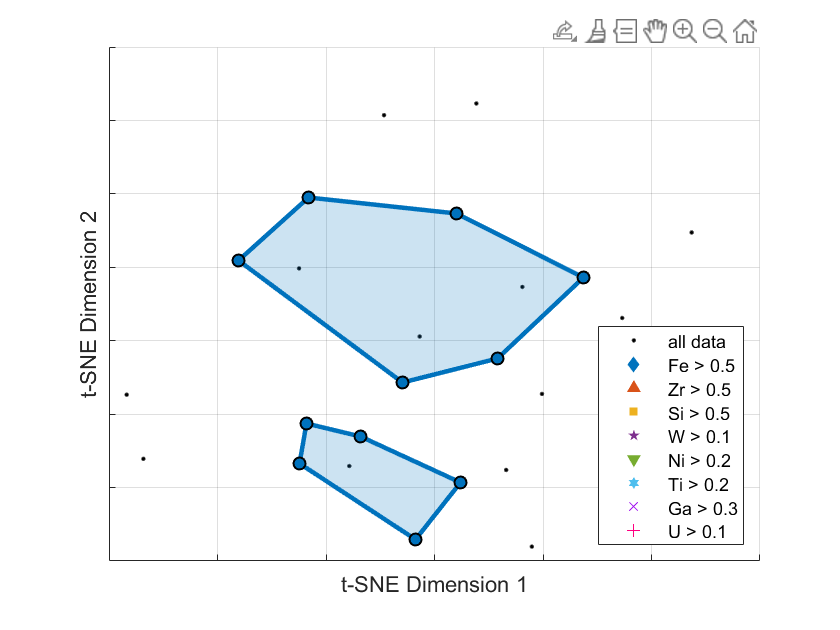

input('hit enter to proceed to next polygon', 's');
subpoly = drawpolygon(tsneax);

## Draw H curves

Now that he have a polygon,  just run the code below to draw the hydrogen lines.

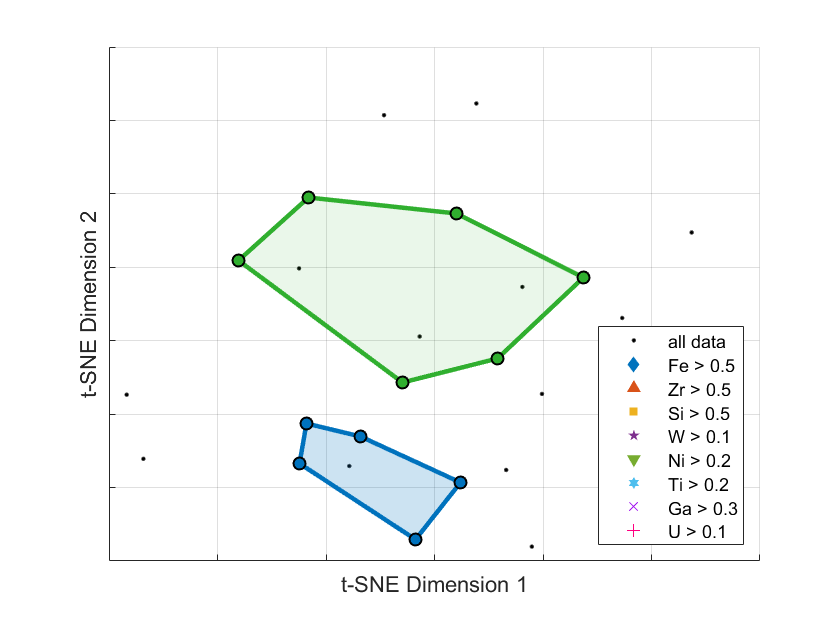

% select a random colour for the polygon and lines later on.
col = rand(1,3);
subpoly.Color = col;

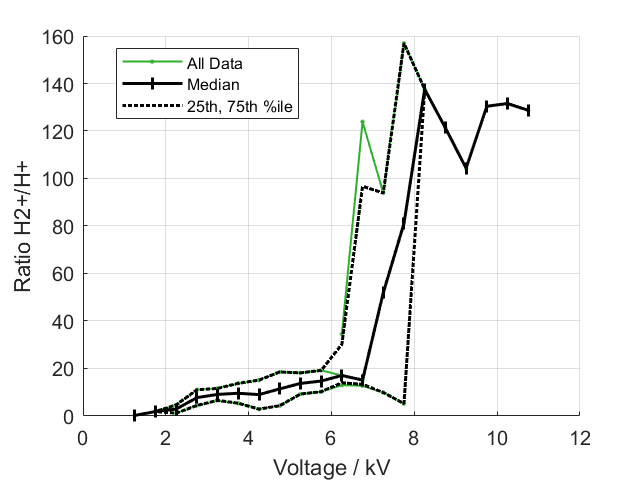

subpoly.FaceAlpha = 0.1;


% open figure for results
fig = figure;
hold on

% get all experiments inside of polygon
in_poly = inpolygon(TsneTab.tsne_x, TsneTab.tsne_y, subpoly.Position(:,1), subpoly.Position(:,2));
in_poly_Tab = TsneTab(in_poly,:);


% Combine the list of experiments in polygon with the list of Hydrogen curves
in_Poly_HTab = innerjoin(in_poly_Tab, HydrogenTab, 'Keys', {'Experiment', 'Experiment'});


% make the tab4avg - this is a table which we will use to hold all hydrogen curves insode of the
% polygon in order to calculate an median and 25/74 percentiles later on.
na = strtrim(string(num2str((voltagebins(1:end-1)+(diff(voltagebins)./2))')));
tabfill = nan([height(in_Poly_HTab), length(na)]);
tab4avg = array2table(tabfill, 'VariableNames', na);


%Iterate through all experiments in polygon,  draw H curve and store in tab4avg
for k2 = 1:height(in_Poly_HTab)   
    
    vcenters = mean(in_Poly_HTab.voltagebins{k2},1);
    if wewanttoplot == "H2byH"
        %plot H2/H
        plotline = in_Poly_HTab.H2absolute{k2}./in_Poly_HTab.Habsolute{k2};
    elseif wewanttoplot == "H2"
        % plot H2
        plotline = 100 .* in_Poly_HTab.H2absolute{k2}./in_Poly_HTab.totalCounts{k2}; %multiply by 100 to plot in percent
    elseif wewanttoplot == "H"
        % plot H
        plotline = 100 .* in_Poly_HTab.Habsolute{k2}./in_Poly_HTab.totalCounts{k2}; %multiply by 100 to plot in percent
    else
        error("wewanttoplot must be one out of H2byH, H2 or H,  as string (not char array)")
    end
    
    if isempty(plotline)
        continue
    end
    
    plts(1) = plot(vcenters./1000, plotline, '.-', 'Color', col, 'LineWidth', 1);
    
    for k3 = 1:length(vcenters)
        tab4avg.(string(num2str(vcenters(k3))))(k2) = plotline(k3);
    end
end


% Add the lines for median and 25, 75 percentiles
avgmat = table2array(tab4avg);
prc = prctile(avgmat, [25 75], 1);
plts(2) = plot(str2double(tab4avg.Properties.VariableNames)./1000, median(avgmat,1,'omitnan'), 'k|-', 'LineWidth', 1.5);
plts(3) = plot(str2double(tab4avg.Properties.VariableNames)./1000, prc(2,:), 'k:', 'LineWidth', 1.5);
plts(4) = plot(str2double(tab4avg.Properties.VariableNames)./1000, prc(1,:), 'k:', 'LineWidth', 1.5);

leg = legend(plts(1:3), {'All Data', 'Median', '25th, 75th %ile'}, 'Location', 'best');
leg.FontSize = 8;


%Add axis labels
xlabel('Voltage / kV');
if wewanttoplot == "H2byH"
    ylabel('Ratio H2+/H+');
elseif wewanttoplot == "H2"
    ylabel('Ionic Fraction H2+ / %');
elseif wewanttoplot == "H"
    ylabel('Ionic Fraction H+ / %');
end